# Code for IS waveform decoding

This notebook reproduces Figures 5 and S1. It also reproduces Tables 7 and S1

This cell loads in the waveform data for each detected interictal spike and **allows you to set the task type **(i.e. what aspect of the IS do you want to predict).

clear
load("datasets_with_spike_waveforms_2000Hz.mat")

% which task would you like to run?
task="east"

task = "east"


animals = [2443,2453,2454,2462,2467,2486,149];

figure(1)
tiledlayout('flow')


% hard coded values from behavioral data for simplicity of regression
% analyses
auc_values = zeros(size(animals));
auc_errors = zeros(length(auc_values),2);
perf_mean = [76.79,53.32,41.6,54.98,46.84,66.18,75.64];
perf_std = [7.594274159,18.91644787,19.48114473,19.17321048,20.64335244,13.21275899,10.15125608];
perf_sem = perf_std./sqrt(5);

si= [2.790405157,1.121471146,0.264131757,1.082092906,0.803936228,0.308300201,0.920021425];

## Run the model fitting

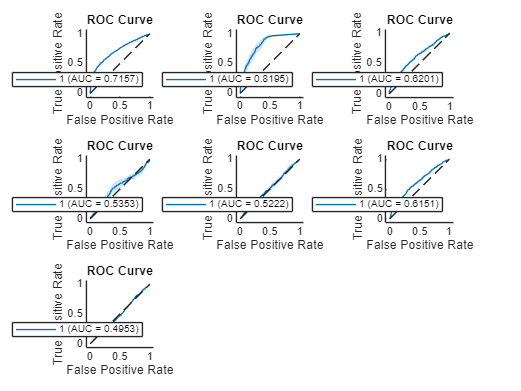

for iii = 1:length(animals)
    wh_animal = animals(iii);
    idx_animal = datasets.animal(:,1) == wh_animal;
    idx_b1_datasets = contains([datasets.sess{:,1}],'b1')';
    
    idx_use = find(idx_b1_datasets.*idx_animal);
    
    all_spikes = [];
    all_bins = [];
    all_solitary = [];
    all_first = [];
    is_correct = [];
    is_east = [];
    
    for i = 1:length(idx_use)
        get_spikes = datasets.data{idx_use(i),6};
        all_bins = [all_bins; datasets.data{idx_use(i),4}];
        all_solitary = [all_solitary; datasets.is_solitary{idx_use(i)}];
        all_birds = datasets.BIRDs{idx_use(i),1}.chain_idx(datasets.BIRDs{idx_use(i),1}.chain_len>0);
        
        % for each spike, find the trial it belongs 
        trial_index = datasets.parsed_path{idx_use(i),1}.TrialIndices;
        trial_times = cell(size(datasets.parsed_path{idx_use(i),1}.TrialIndices));
        for j = 1:length(trial_times)
            trial_times{1,j} = [datasets.parsed_path{idx_use(i),1}.BinnedPath(trial_index{1,j}(1),1),...
                datasets.parsed_path{idx_use(i),1}.BinnedPath(trial_index{1,j}(2),1)];
        end
    
        BIRD_init = zeros(size(all_solitary));
        for b = 1:length(all_birds)
           BIRD_init(all_birds{b}(1)) = 1;
        end
        all_first = [all_first; BIRD_init];
        for j = 1:length(get_spikes(:,1))
            all_spikes(end+1,:) = get_spikes(j,:);
        end
        
        temp_correct = nan(height(get_spikes),1);
        temp_direction = nan(height(get_spikes),1);
        for j = 1:length(trial_times)
            [~,start_i] = min(abs(datasets.data{idx_use(i),1}-trial_times{1,j}(1)));
            [~,stop_i] = min(abs(datasets.data{idx_use(i),1}-trial_times{1,j}(2)));
    
            temp_correct(start_i:stop_i) = repmat(contains(datasets.parsed_path{idx_use(i),1}.Evaluate{j,2},'Correct'),length(temp_correct(start_i:stop_i)),1);
            temp_direction(start_i:stop_i) = repmat(contains(datasets.parsed_path{idx_use(i),1}.Evaluate{j,1},'E'),length(temp_correct(start_i:stop_i)),1);
        end
        is_correct = [is_correct;temp_correct];
        is_east = [is_east;temp_direction];
    end
    
    rng(1234)
    all_spikes = (all_spikes-mean(all_spikes,'all'))/std(all_spikes,0,'all');
    
    size_of_sig = zeros(length(all_spikes),1);
    for i = 1:length(is_correct)
        size_of_sig(i) = peak2peak(smooth(all_spikes(i,:),100));
    end
    
    is_reward = all_bins >= 3;
    is_delay_or_choice = (all_bins == 1);
    subset_all_spikes = all_spikes;
    embed_spikes=tsne(subset_all_spikes);
    
    rng(1234)
    if contains(task,"rew")
        SVMModel = fitcensemble(embed_spikes,is_reward,"Method","Bag");
    elseif contains(task,"corr")
        SVMModel = fitcensemble(embed_spikes,is_correct,"Method","Bag");
    elseif contains(task,"east")
        SVMModel = fitcensemble(embed_spikes,is_east,"Method","Bag");
    else
        error("Select a valid task type!")
    end

    
    CVSVMModel = crossval(SVMModel,KFold=5);
    [labelPred,scorePred] = kfoldPredict(CVSVMModel);
    rocObj = rocmetrics(CVSVMModel);
    [auc_score,l_auc,u_auc]=auc(rocObj);

    auc_values(iii) = auc_score(1);
    auc_errors(iii,1) = l_auc(1);
    auc_errors(iii,2) = u_auc(1);
    
    figure(1)
    nexttile()
    plot(rocObj,ShowConfidenceIntervals=true,ClassNames=1,ShowModelOperatingPoint=false)
end

## Regression analysis

pmodel = Figure 5 regression model and Table 7 (depending on what task you have just run)

pmodel_si = Table S1 regression model

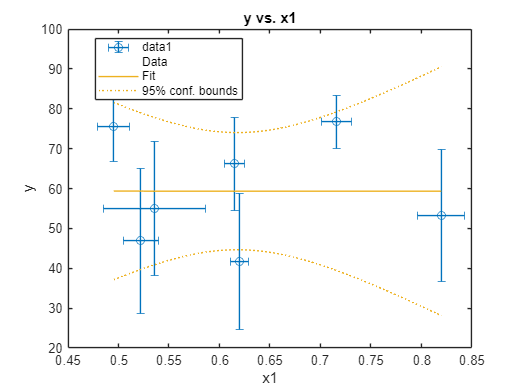

pmodel = fitlm(auc_values,perf_mean);

figure()
errorbar(auc_values,perf_mean,1.96*perf_sem,1.96*perf_sem,auc_values'-auc_errors(:,1),auc_errors(:,2)-auc_values','o')
hold on
plot(pmodel,'Marker','none')
hold off


pmodel_si = fitlm([si',auc_values'],perf_mean,"VarNames",{'SI','AUC','Perf'});